str = "kulakov";
dis = sprintf("Изначальное сообщение: %s\n", str);
disp(dis);

Изначальное сообщение: kulakov



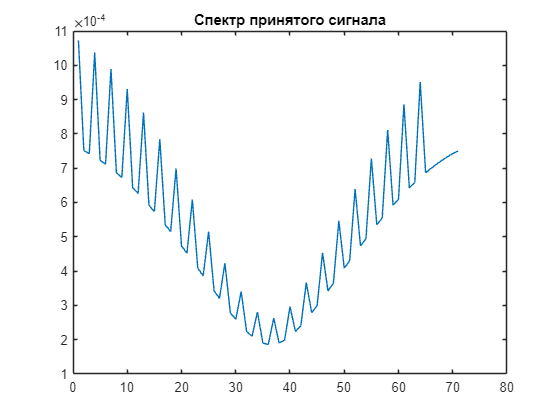

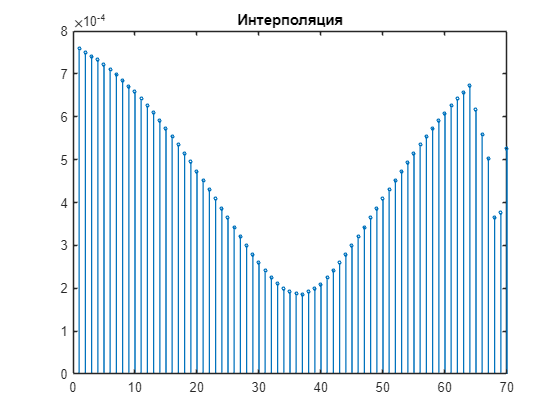

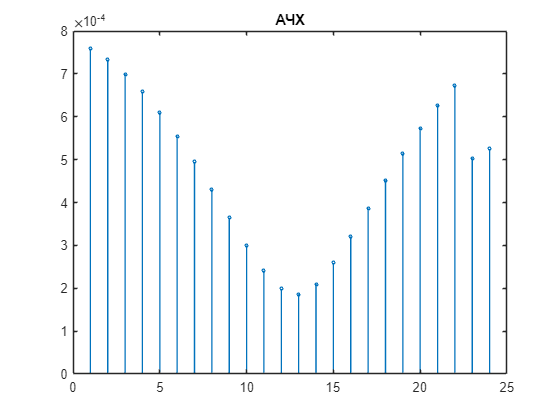

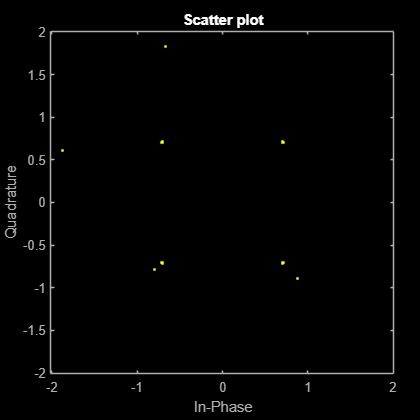


Декодированное сообщение: kulakov


bit = 7;
x = char(str);
BERS = [];
DB = [];

DRS = 3;
pref = 1/4;

Nb = 2;
B = 11*10^6;
F0 = 1.7* 10^9;
N0 = 0;

output = 2;

massage = encode(x);
for i=1:1

    if output == 1
        dis = sprintf("Битовая последовательность: \n");
        disp(dis);
        disp(num2str(massage));
        dis = sprintf("\nБитовая последовательность после шифрования: \n");
        disp(dis);
    end


    conv_massage = conv_encode(massage);
    

    if output == 1
        disp(num2str(conv_massage));
    end
    %----------------------------------
    ran_index = randperm(length(conv_massage));
    
    if output == 1
        dis = sprintf("\nВектор перемежения: \n");
        disp(dis);
        disp(num2str(ran_index));
    end

    interleave_massage = interleave(conv_massage, ran_index);

    if output == 1
        dis = sprintf("\nБитовая последовательность после перемежения: \n");
        disp(dis);
        disp(num2str(interleave_massage));
    end
    %----------------------------------
    qpsk_sequence = qpsk_modulation(interleave_massage); % модуляция qpsk

    if output == 1
        fprintf('Mодуляция qpsk: ');
        for t = 1:length(qpsk_sequence)
            fprintf("%g+%gi\t", real(qpsk_sequence(t)), imag(qpsk_sequence(t)));
            if(mod(t, 8) == 0)
                fprintf("\n");
            end
        end
        fprintf("\n");
        % Отображение QPSK символов на комплексной плоскости
        scatter(real(qpsk_sequence), imag(qpsk_sequence), 'filled');
        xlabel('Действительная часть');
        ylabel('Мнимая часть');
        title('QPSK модуляция');
        grid on;
        axis equal;
    end

    %----------------------------------
    [ofdm, Nz, prefix, N_qpsk,pilot, ofdm_len] = ofdm_modulation(qpsk_sequence, DRS, pref);

    if output == 1
        disp("OFDM");
        disp(ofdm);
        fprintf('Mодуляция ofdm: ');
        plot(abs(fft(ofdm)));
        xlabel("Time (sec)");
        ylabel("Amplitude");
        title("OFDM модуляция");
    end
    %-----------------------------------
    %N0 = N0-10;
    N0 = -180;
    DB(i) = N0;
    L = length(ofdm);
    Srx = multibeam(Nb,L,B,F0,N0, ofdm);
    
    if output == 1
        
        fprintf("Srx: ");
        disp(Srx);
        scatterplot(fft(Srx));
        xlabel("Time (sec)");
        ylabel("Amplitude");
        title("Сигнал после многолучевого канала");
    end
    %----------------------------------
    
    [signal, Heq, H, c] = ofdm_demodulation(Srx, Nz,DRS,pilot, prefix, ofdm_len);
    
    if output == 2
        figure;
        plot(abs(c));
        title('Спектр принятого сигнала')
        
        figure;
        stem(abs(Heq), 'MarkerSize', 2, 'LineWidth', 1);
        title('Интерполяция')
    
        figure;
        stem(abs(H), 'MarkerSize', 2, 'LineWidth', 1);
        title('АЧХ');
    
        scatterplot(signal);
    end
    
    qpsk_desequence = qpsk_demodulation(signal); % демодуляция qpsk
    
    if output == 1
        fprintf("Демодуляция qpsk: ");
        for t = 1:length(qpsk_desequence)
        fprintf("%d  ",qpsk_desequence(t));
        end
        fprintf("\n");
    end
    deinterleave_massage = deinterleave(qpsk_desequence, ran_index);
    if output == 1
        dis = sprintf("\nБитовая последовательность после деперемежения: \n");
        disp(dis);
        disp(num2str(deinterleave_massage));
        disp(num2str(interleave_massage));
        
        dis = sprintf("\nБитовая последовательность после дешифрования: \n");
        disp(dis);
        disp(num2str(massage));
    end
    conv_decode_massage = conv_decode(deinterleave_massage, bit);
    BER = calculate_ber(massage, conv_decode_massage);
    BERS(i) = BER;
    if output == 1
        disp(num2str(conv_decode_massage));
    end
    massage_str = decode(conv_decode_massage, bit);
    dis = sprintf("\nДекодированное сообщение: %s", massage_str);
    disp(dis);
end

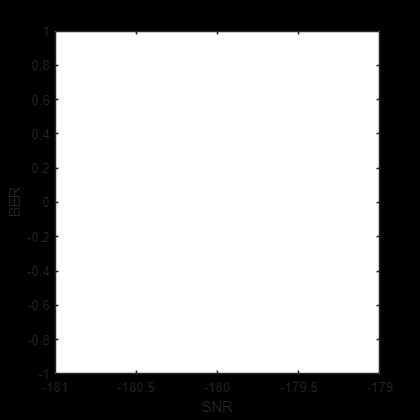


plot(DB,BERS);
xlabel("SNR");
ylabel("BER");
title("BER");